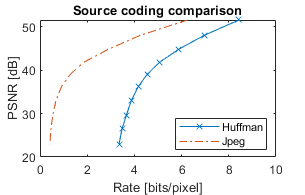

%General stuff/variables
origImage = 'image1.png';

blocksize = [4 4];
%blocksize = [8 8];
%blocksize = [16 16];

qy = 0.1;
qc = 0.1;

transformType = 'dct';
%transformType = 'dwht';

numberOfSteps = 10;
lowerStepsize = 0.005;
upperStepsize = 0.5;

stepSizes = logspace(log10(lowerStepsize), log10(upperStepsize), numberOfSteps);
bpp = zeros(length(stepSizes), 1);
psnr = zeros(length(stepSizes), 1);
sampleFactor = 1;

%***************************************************************************************************%
% What source coding method gives the smallest rates?
%***************************************************************************************************%

%Huffman
%huffmanOrJpeg = 'huffman';
for i = 1:length(stepSizes)
    [bits, bpp(i), dist, psnr(i)] = transcoder(origImage, blocksize, stepSizes(i), stepSizes(i),transformType, 'huffman',...
        sampleFactor);
end

plot(bpp, psnr, '-x');

hold on

% %Seperate Huffman
% huffmanOrJpeg = 'sepHuffman';
% for i = 1:length(stepSizes)
%     [bits, bpp(i), dist, psnr(i)] = transcoder(origImage, blocksize, stepSizes(i), stepSizes(i),transformType, huffmanOrJpeg,...
%         sampleFactor);
% end
% 
% plot(bpp, psnr, '-x');

%JPEG
huffmanOrJpeg = 'jpeg';
for i = 1:length(stepSizes)
    [bits, bpp(i), dist, psnr(i)] = transcoder(origImage, blocksize, stepSizes(i), stepSizes(i),transformType, 'jpeg',...
        sampleFactor);
end

plot(bpp, psnr, '-.');
hold off

xlabel('Rate [bits/pixel]')
ylabel('PSNR [dB]')
legend('Huffman', 'Jpeg', 'Location', 'southeast')
title('Source coding comparison')

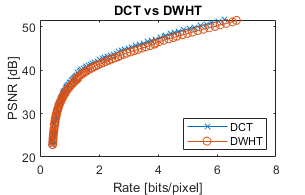

%***************************************************************************************************%
% What choice of transform (DCT or DWHT) gives the best results?
%***************************************************************************************************%

clear
origImage = 'image1.png';
blocksize = [4 4];
%blocksize = [8 8];
%blocksize = [16 16];
sampleFactor = 1;

numberOfSteps = 100;
lowerStepsize = 0.005;
upperStepsize = 0.5;

stepSizes = logspace(log10(lowerStepsize), log10(upperStepsize), numberOfSteps);

bpp_Dct = zeros(length(stepSizes), 1);
psnr_Dct = zeros(length(stepSizes), 1);

bpp_Dwht = zeros(length(stepSizes), 1);
psnr_Dwht = zeros(length(stepSizes), 1);

for i = 1:length(stepSizes)
        [bits, bpp_Dct(i), dist, psnr_Dct(i)] = transcoder(origImage, blocksize, stepSizes(i), stepSizes(i),'dct', 'jpeg',...
        sampleFactor);
        [bits, bpp_Dwht(i), dist, psnr_Dwht(i)] = transcoder(origImage, blocksize, stepSizes(i), stepSizes(i),'dwht', 'jpeg',...
        sampleFactor);
end

plot(bpp_Dct, psnr_Dct, '-x');
hold on
plot(bpp_Dwht, psnr_Dwht, '-o');
xlabel('Rate [bits/pixel]')
ylabel('PSNR [dB]')
legend('DCT', 'DWHT', 'Location', 'southeast')
title('DCT vs DWHT')
hold off

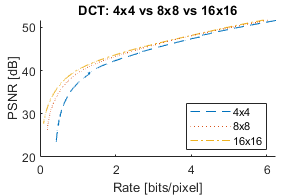

%***************************************************************************************************%
% What choice of block size gives the best results?
%***************************************************************************************************%
transformType = 'dct';
stepSizes = logspace(log10(0.005), log10(0.5), 500);
bpp = zeros(length(stepSizes), 1);
psnr = zeros(length(stepSizes), 1);

for i = 1:length(stepSizes)
    [bits, bpp(i), dist, psnr(i)] = transcoder(origImage, [4 4], stepSizes(i), stepSizes(i),transformType, 'jpeg',...
        sampleFactor);
end

plot3(bpp, psnr, 1:length(bpp), '--');
hold on


for i = 1:length(stepSizes)
    [bits, bpp(i), dist, psnr(i)] = transcoder(origImage, [8 8], stepSizes(i), stepSizes(i),transformType, 'jpeg',...
        sampleFactor);
end

plot3(bpp, psnr, 1:length(bpp), ':');


for i = 1:length(stepSizes)
    [bits, bpp(i), dist, psnr(i)] = transcoder(origImage, [16 16], stepSizes(i), stepSizes(i),transformType, 'jpeg',...
        sampleFactor);
end

plot3(bpp, psnr, 1:length(bpp), '-.');
hold off
view(0,90)
xlabel('Rate [bits/pixel]')
ylabel('PSNR [dB]')
legend('4x4', '8x8', '16x16', 'Location', 'southeast')
title('DCT: 4x4 vs 8x8 vs 16x16')

%***************************************************************************************************%
% What quantization method gives the best results, using the same stepsize
% for all transform components or using different stepsizes for different
% transform components?
%***************************************************************************************************%
transformType = 'dct';
stepSizes = logspace(log10(1.5), log10(3.5), 50);
bpp1 = zeros(length(stepSizes), 1);
psnr1 = zeros(length(stepSizes), 1);
bpp2 = zeros(length(stepSizes), 1);
psnr2 = zeros(length(stepSizes), 1);

sampleFactor = 0;
QL=repmat(1:16, 16, 1); 
QL=(QL+QL'-17)/16;
k2=0.9;

for i = 1:length(stepSizes)
    [bits, bpp1(i), dist, psnr1(i)] = transcoder(origImage, [16 16], stepSizes(i)*0.1, stepSizes(i)*0.1,transformType, 'jpeg',...
        sampleFactor);
end

for i = 1:length(stepSizes)
    [bits, bpp2(i), dist, psnr2(i)] = transcoder(origImage, [16 16], stepSizes(i)*(1+k2*QL)*0.1, stepSizes(i)*(1+k2*QL)*0.1,transformType, 'jpeg',...
        sampleFactor);
end

plot3(bpp1, psnr1, 1:length(bpp1), '-.');
hold on
plot3(bpp2, psnr2, 1:length(bpp2), '--');
hold off
view(0,90)
xlabel('Rate [bits/pixel]')
ylabel('PSNR [dB]')
legend('Same', 'Different', 'Location', 'southeast')
title('Different vs same stepsize')

%I don't even know, he said that this was a hard one he didn't expect
%everyone to get so imma give up on it rn.

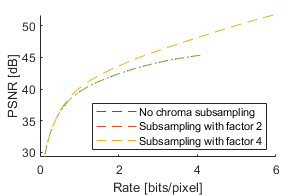

%***************************************************************************************************%
% How does the chrominance subsampling affect the results?
%***************************************************************************************************%

transformType = 'dct';
origImage = 'image1.png';
stepSizes = logspace(log10(0.005), log10(0.3), 100);
bpp = zeros(length(stepSizes), 1);
psnr = zeros(length(stepSizes), 1);

sampleFactor = 0;
for i = 1:length(stepSizes)
        [bits, bpp(i), dist, psnr(i)] = transcoder(origImage, [16 16], stepSizes(i), stepSizes(i),transformType, 'jpeg',...
        sampleFactor);
end

plot3(bpp, psnr, 1:length(bpp), '--');
hold on

sampleFactor = 2;
for i = 1:length(stepSizes)
        [bits, bpp(i), dist, psnr(i)] = transcoder(origImage, [16 16], stepSizes(i), stepSizes(i),transformType, 'jpeg',...
        sampleFactor);
end

plot3(bpp, psnr, 1:length(bpp), ':');

sampleFactor = 4;
for i = 1:length(stepSizes)
        [bits, bpp1(i), dist, psnr1(i)] = transcoder(origImage, [16 16], stepSizes(i), stepSizes(i),transformType, 'jpeg',...
        sampleFactor);
end

plot3(bpp, psnr, 1:length(bpp), '-.');
hold off
view(0,90)
xlabel('Rate [bits/pixel]')
ylabel('PSNR [dB]')
legend('No chroma subsampling', 'Subsampling with factor 2', 'Subsampling with factor 4', 'Location', 'southeast')

%Low subsampling does nothing major (blue and yellow are mixing to make
%green), a slightly higher subsampling factor actually makes it better.


origImage = 'image4.png'

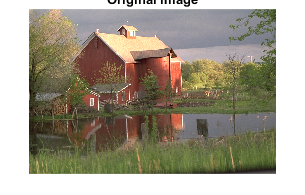

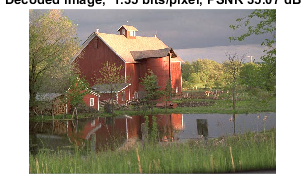

%***************************************************************************************************%
% What is the lowest rate (in bits per pixel) that gives coded images that
% are indestinguishable from the original image at a normal viewing
% distance?
%***************************************************************************************************%

origImage = 'image4.png'

blocksize = [16 16];
qy = 0.05;
qc = 0.05;
sampleFactor = 2;
transformType = 'dct';

transcoder(origImage, blocksize, qy, qc, transformType, 'jpeg', sampleFactor);
%Looks good


%***************************************************************************************************%
% What is the lowest rate that gives an acceptable image quality?
%***************************************************************************************************%

origImage = 'image4.png'

origImage = 'image4.png'

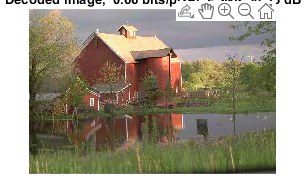

blocksize = [16 16];
qy = 0.1;
qc = 0.1;
sampleFactor = 2;
transformType = 'dct';

transcoder(origImage, blocksize, qy, qc, transformType, 'jpeg', sampleFactor);